# **Analysis: fixed analysis C202**

Cell line: MCF10A, FUCCI-CA cterm, NR67(pCW_ND-GMNN-HA)

Microscope: Nikon 10x CFP-Cherry triggered 

Imaging: 3 min interval, EdU pulse 30 min before fixation

**Testing for:**

- Cdt1 levels after CRL4 activation

- EdU levels, w/ w/o ND-GMNN

**Annotations**

- CRL4 degradation start (using 5 future frames of drop = 15 min)

- Thresholds for IF

## **Load Data**

cd('F:\Data\C-Cdt1\Figures\Paper\CActerm');
S = {};
clear data
%%% C202
conditions = {
        'DMSO',4,2:11,1:9,[0 0 0]; %1
        'DOX',5,2:11,1:9,[0 0 0]; %1  
};
% dataDir = 'F:\Data\C-Cdt1\C202-live\Data\';
% data = loadData_C202(conditions, dataDir);
data = load(['C202_data.mat'],'S');
data = data.S;
[data.conditions] = deal(conditions);
[data.framesPerHr] = deal(60/3);
[data.numFrames] = deal(size(data(1).area,2));
[data.xFrames] = deal(1:data(1).numFrames);
[data.xTime] = deal((data(1).xFrames-1)./data(1).framesPerHr);
[data.experiment] = deal('C202');
map = nikon_well_offset_new(conditions,9,1);
POI_time = arrayfun(@(x) (x.numFrames - x.POI + repmat(cell2mat(map.values(x.shot)),1,size(x.POI,2)))/x.framesPerHr, data,'UniformOutput',false);
[data.POI_time] = POI_time{:};


S = [S {data}];

clear data
%%% C205
conditions = {
         'DMSO',4,2:11,1:9,[0 0 0]; %1
         'DOX',5:6,2:11,1:9,[0 0 0]; %1
};
dataDir = 'F:\Data\C-Cdt1\C205-live\Data\';
% data = loadData_C205(conditions, dataDir);
data = load(['C205_data.mat'],'S');
data = data.S;
[data.conditions] = deal(conditions);
[data.framesPerHr] = deal(60/3);
[data.numFrames] = deal(size(data(1).area,2));
[data.xFrames] = deal(1:data(1).numFrames);
[data.xTime] = deal((data(1).xFrames-1)./data(1).framesPerHr);
[data.experiment] = deal('C205');
map = nikon_well_offset_new(conditions,9,1);
POI_time = arrayfun(@(x) (x.numFrames - x.POI + repmat(cell2mat(map.values(x.shot)),1,size(x.POI,2)))/x.framesPerHr, data,'UniformOutput',false);
[data.POI_time] = POI_time{:};


S = [S {data}];

clear data
%%% C206
conditions = {
         'DMSO',2:4,2:5,1:9,[0 0 0]; %1
         'DOX',2:4,6:10,1:9,[0 0 0]; %1
};
dataDir = 'F:\Data\C-Cdt1\C206-live\Data\';
% data = loadData_C206(conditions, dataDir);
data = load(['C206_data.mat'],'S');
data = data.S;
[data.conditions] = deal(conditions);
[data.framesPerHr] = deal(60/3);
[data.numFrames] = deal(size(data(1).area,2));
[data.xFrames] = deal(1:data(1).numFrames);
[data.xTime] = deal((data(1).xFrames-1)./data(1).framesPerHr);
[data.experiment] = deal('C206');
map = nikon_well_offset_new(conditions,9,1);
POI_time = arrayfun(@(x) (x.numFrames - x.POI + repmat(cell2mat(map.values(x.shot)),1,size(x.POI,2)))/x.framesPerHr, data,'UniformOutput',false);
[data.POI_time] = POI_time{:};


S = [S {data}];



**Set gates**

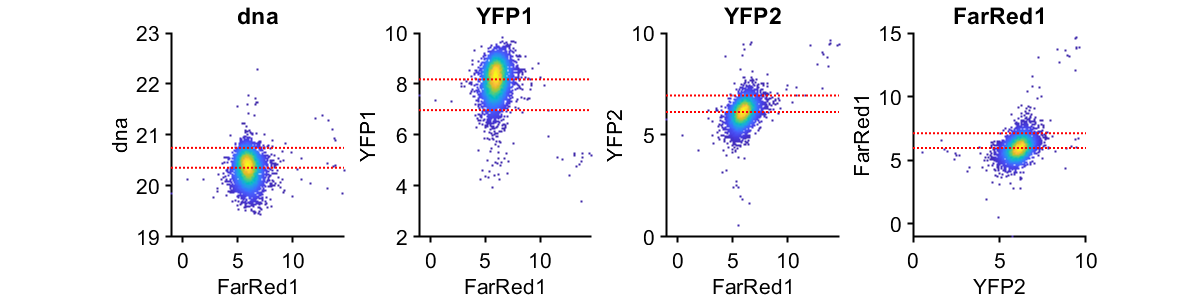

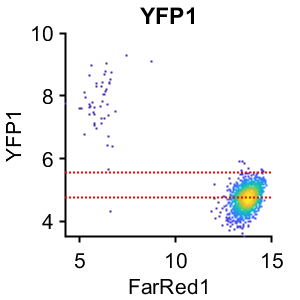

medEdU = 9.4484e+03

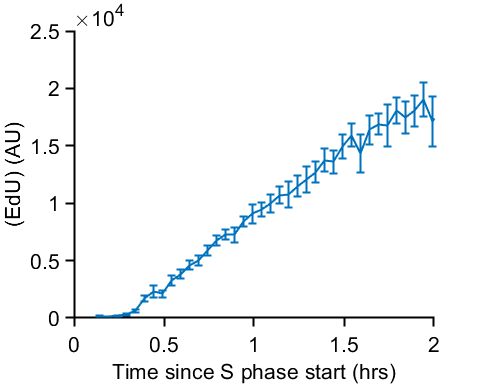

cells = 2965

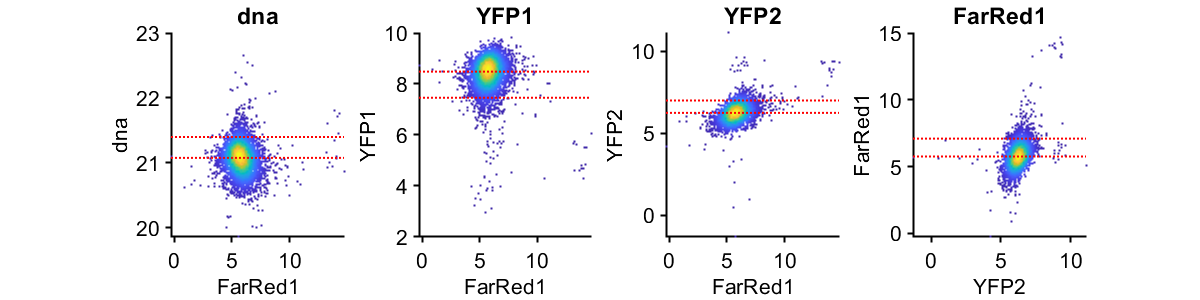

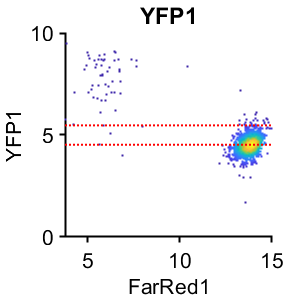

medEdU = 1.0143e+04

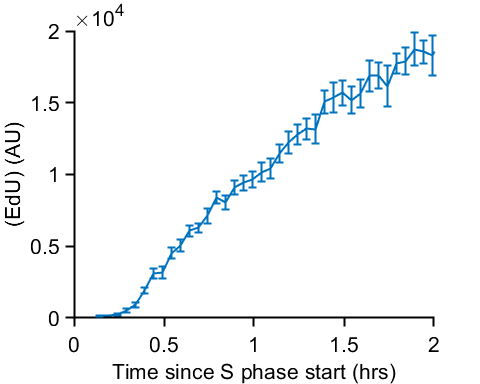

cells = 4222

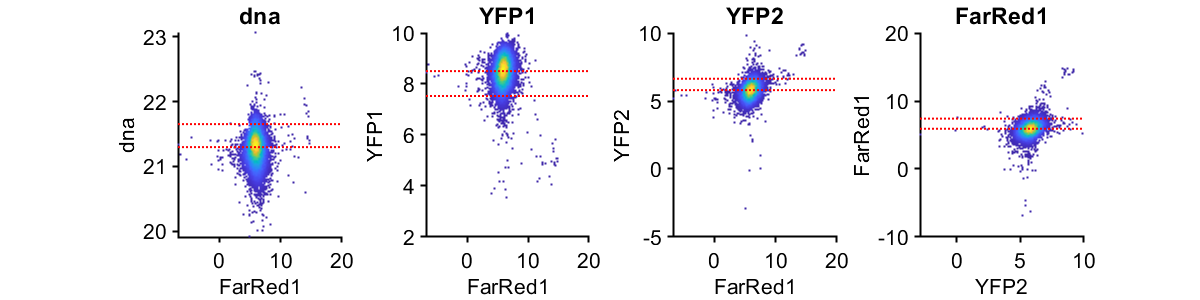

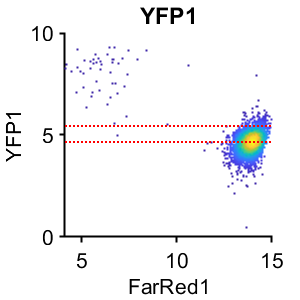

medEdU = 1.0691e+04

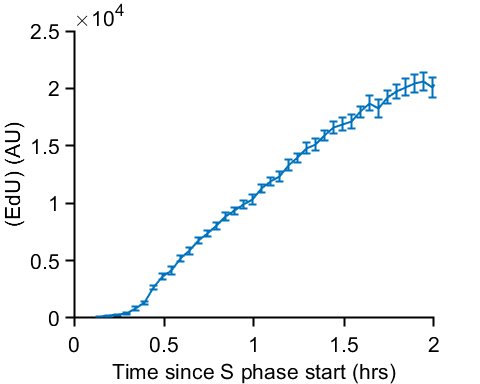

cells = 9552

gates_all = {};
medEdU_all = [];

for j = [1:3]
    dat = S{j};
    %% Set gates time after mitosis
    cond=1;
    gate = struct();
    gates = {'dna','YFP1','YFP2','FarRed1'};
    plotting = {'FarRed1','FarRed1','FarRed1','YFP2'};
    prctiles = {[50 95], [5 50],[50 95],[50 95]};
    
    figure('pos',[0 0 length(gates)*300 300 ])
    
    for i = 1:length(gates)
        inds = dat(cond).POI_time(:,1) <= 2 & dat(cond).POI_time(:,1) > 1 ;
        ydata = dat(cond).(gates{i})(inds,:);
        xdata = dat(cond).(plotting{i})(inds,:);
        
        gate.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
        
        subplot(1,length(gates),i)
        dscatter(log2(xdata),log2(ydata));
        hline( log2(gate.([gates{i} '_G1'])))
        ylabel(gates{i});
        xlabel(plotting{i});
        title(gates{i});
        
    end
    
    %% set S phase gates
    cond=1;
    gates = {'YFP1'};
    plotting = {'FarRed1'};
    prctiles = {[50 95]};
    
    figure('pos',[0 0 length(gates)*300 300 ])
    
    for i = 1:length(gates)
        inds = dat(cond).POI_time(:,3) <= 2 &  dat(cond).POI_time(:,3) > 1 ;
        ydata = dat(cond).(gates{i})(inds,:);
        xdata = dat(cond).(plotting{i})(inds,:);
        
        gate.([gates{i} '_S']) = prctile(ydata, prctiles{i});
        
        subplot(1,length(gates),i)
        dscatter(log2(xdata),log2(ydata));
        hline( log2(gate.([gates{i} '_S'])))

        ylabel(gates{i});
        xlabel(plotting{i});
        title(gates{i});
               
    end
    
    %% Set S phase 1-1.2 hrs median
    cond=1;
    gates = {'FarRed1'};
    prctiles = {[50]};
    
    figure('pos',[0 0  300 300 ])
    
    inds = dat(cond).POI_time(:,3) <= 1.2 & dat(cond).POI_time(:,3) > 1 ;
    ydata = dat(cond).(gates{i})(inds,:);
    
    medEdU = prctile(ydata, prctiles{i})
    
    gates_all = [gates_all, gate];
    medEdU_all = [medEdU_all medEdU];
    
    
    %% SHow
    
    figure('Units', 'Inches', 'Position', [0, 0, 5, 4]);        
    % range = linspace(0,4,10);
    edges = (0:1/dat(1).framesPerHr:10);
    midpoints = edges + (edges(2) -edges(1))/2;
    midpoints = midpoints(1:end-1);
    
    inds = ~isnan(dat(cond).POI_time(:,3));
    xdata = dat(cond).POI_time(inds,3);
    ydata = dat(cond).FarRed1(inds) ;
    
    
    [binData, edges] = bin_xy(xdata, ydata, {'mean','median'}, 'Edges',edges);
    
    
    hold on
    errorbar(midpoints-1/12,binData.mean,2*binData.sem,'LineWidth',1.5);
    xlabel('Time since S phase start (hrs)');
    ylabel('(EdU) (AU)');
    % h=hline(log2(gate.FarRed1_G1),'k--');
    %     ylim([4.5 14.5]);
    xlim([0 2]);
    hold off
    cells = length(xdata)
    
end

Save data

save('alldata.mat','S','gates_all','medEdU_all','-v7.3');